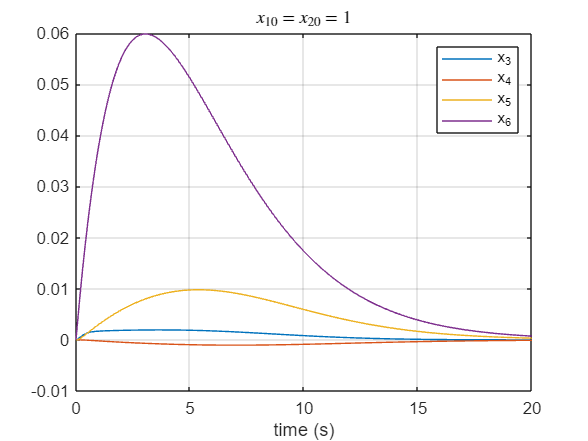

clear; close all;

x10 = 1;
x20 = 1;
[t,y] = ode45(@f, [0 20], [x10;x20;0;0;0;0]);

figure
plot(t,y(:,3:end))
legend('x_3','x_4','x_5','x_6','Location','northeast')
grid on
xlabel('time (s)')
title('$x_{10}=x_{20}=1$','Interpreter','latex')

function [dydt] = f(~,y)

hp = @(x) polyval([418.6 -905.24 688.86 -207.58 17.76], x);
h = @(x) polyval([83.72 -226.31 229.62 -103.79 17.76 0],x);

dydt = zeros(6,1);
x1 = y(1);
x2 = y(2);
x3 = y(3);
x4 = y(4);
x5 = y(5);
x6 = y(6);
dydt(1) = 0.5*(-h(x1)+x2);
dydt(2) = 0.2*(-x1-1.5*x2+1.2);
dydt(3) = 0.5*(-hp(x1)*x3+x4)-0.25*(-h(x1)+x2);
dydt(4) = 0.2*(-x3 - 1.5*x4);
dydt(5) = 0.5*(-hp(x1)*x5+x6);
dydt(6) = 0.2*(-x5-1.5*x6) - 0.04*(-x1-1.5*x2+1.2);
end
